Colin Keenan

ECE 5470

3-25-2020

# Midterm

1.  Apply Various 3x3 Filters to Pattern1.jpg and Pattern2.jpg

## Arithmetic Mean Filter

clear

fprintf("Question 1, Arithmetic Mean Filter:")

Question 1, Arithmetic Mean Filter:

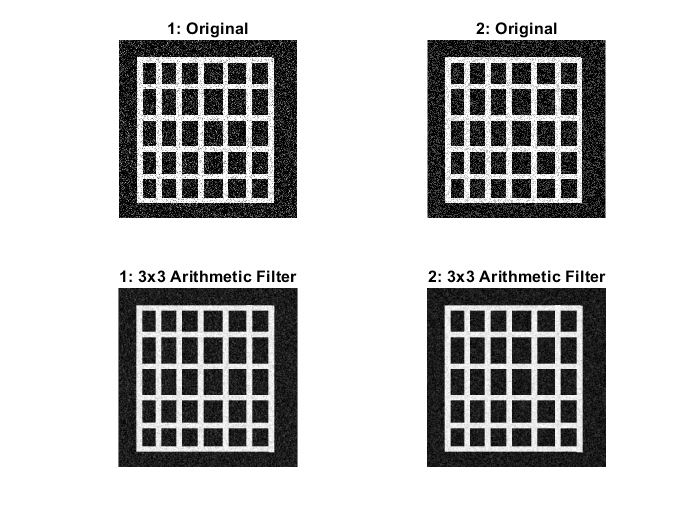


A_image = im2double(imread('Pattern1.jpg'));
B_image = im2double(imread('Pattern2.jpg'));

A_image_mod_3x3 = zeros(size(A_image));
B_image_mod_3x3 = zeros(size(B_image));

mask_3x3 = [[1 1 1]
             [1 1 1]
             [1 1 1]];
mask_weight = sum(sum(mask_3x3));

for i = 1+1 : size(A_image,1)-1
    for j = 1+1 : size(A_image,2)-1
        
        frame_3x3 = [[A_image(i-1,j-1) A_image(i-1,j+0) A_image(i-1,j+1)]
                     [A_image(i+0,j-1) A_image(i+0,j+0) A_image(i+0,j+1)]
                     [A_image(i+1,j-1) A_image(i+1,j+0) A_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        A_image_mod_3x3(i,j) = sum(sum(masked)) / mask_weight;
        
    end
end
        
for i = 1+1 : size(B_image,1)-1
    for j = 1+1 : size(B_image,2)-1
        
        frame_3x3 = [[B_image(i-1,j-1) B_image(i-1,j+0) B_image(i-1,j+1)]
                     [B_image(i+0,j-1) B_image(i+0,j+0) B_image(i+0,j+1)]
                     [B_image(i+1,j-1) B_image(i+1,j+0) B_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        B_image_mod_3x3(i,j) = sum(sum(masked)) / mask_weight;
        
    end
end

figure();
subplot(2,2,1)
imshow(A_image);
title("1: Original");
subplot(2,2,2)
imshow(B_image);
title("2: Original");
subplot(2,2,3)
imshow(A_image_mod_3x3);
title("1: 3x3 Arithmetic Filter");
subplot(2,2,4)
imshow(B_image_mod_3x3);
title("2: 3x3 Arithmetic Filter");

Explanation: As you can see in the images, there is not a big difference between the two noise patterns, post 3x3 arithmetic filters, but pattern 2 was cleaned up slightly better in the dark areas with a similar performance between 1 and 2 in the light areas.

## Geometric Mean Filter

clear

fprintf("Question 1, Geometric Mean Filter:")

Question 1, Geometric Mean Filter:

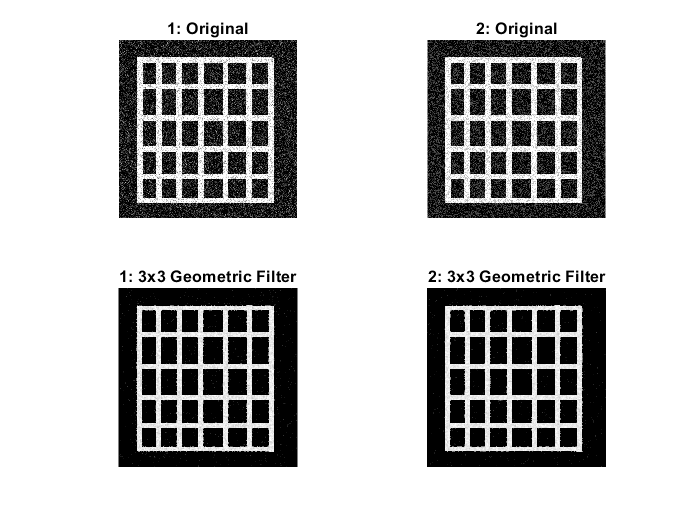


A_image = im2double(imread('Pattern1.jpg'));
B_image = im2double(imread('Pattern2.jpg'));

A_image_mod_3x3 = zeros(size(A_image));
B_image_mod_3x3 = zeros(size(B_image));

mask_3x3 = [[1 1 1]
            [1 1 1]
            [1 1 1]];
mask_weight = sum(sum(mask_3x3));

for i = 1+1 : size(A_image,1)-1
    for j = 1+1 : size(A_image,2)-1
        
        frame_3x3 = [[A_image(i-1,j-1) A_image(i-1,j+0) A_image(i-1,j+1)]
                     [A_image(i+0,j-1) A_image(i+0,j+0) A_image(i+0,j+1)]
                     [A_image(i+1,j-1) A_image(i+1,j+0) A_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        A_image_mod_3x3(i,j) = prod(prod(masked)) ^ (1/mask_weight);
        
    end
end
               
for i = 1+1 : size(B_image,1)-1
    for j = 1+1 : size(B_image,2)-1
        
        frame_3x3 = [[B_image(i-1,j-1) B_image(i-1,j+0) B_image(i-1,j+1)]
                     [B_image(i+0,j-1) B_image(i+0,j+0) B_image(i+0,j+1)]
                     [B_image(i+1,j-1) B_image(i+1,j+0) B_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        B_image_mod_3x3(i,j) = prod(prod(masked)) ^ (1/mask_weight);
        
    end
end

figure();
subplot(2,2,1)
imshow(A_image);
title("1: Original");
subplot(2,2,2)
imshow(B_image);
title("2: Original");
subplot(2,2,3)
imshow(A_image_mod_3x3);
title("1: 3x3 Geometric Filter");
subplot(2,2,4)
imshow(B_image_mod_3x3);
title("2: 3x3 Geometric Filter");

Explanation: As you can see in the images, the geometric mean filter does a much better job at the darker areas cleaning up the noise when compared to the arithmetic mean filter. However, in the lighter areas, it has a similar if not worse performance in that some of the edges of the white areas now have small protrusions.

## Harmonic Mean Filter

clear

fprintf("Question 1, Harmonic Mean Filter:")

Question 1, Harmonic Mean Filter:

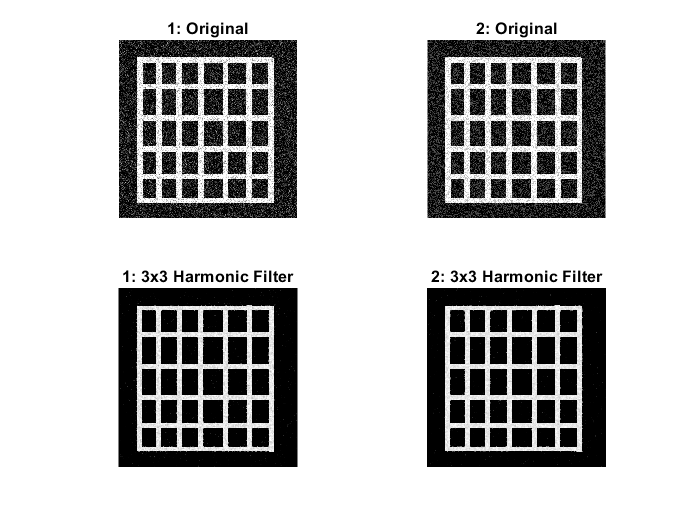


A_image = im2double(imread('Pattern1.jpg'));
B_image = im2double(imread('Pattern2.jpg'));

A_image_mod_3x3 = zeros(size(A_image));
B_image_mod_3x3 = zeros(size(B_image));

mask_3x3 = [[1 1 1]
            [1 1 1]
            [1 1 1]];
mask_weight = sum(sum(mask_3x3));

for i = 1+1 : size(A_image,1)-1
    for j = 1+1 : size(A_image,2)-1
        
        frame_3x3 = [[A_image(i-1,j-1) A_image(i-1,j+0) A_image(i-1,j+1)]
                     [A_image(i+0,j-1) A_image(i+0,j+0) A_image(i+0,j+1)]
                     [A_image(i+1,j-1) A_image(i+1,j+0) A_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        A_image_mod_3x3(i,j) = mask_weight / sum(sum(1./masked));
    end
end
               
for i = 1+1 : size(B_image,1)-1
    for j = 1+1 : size(B_image,2)-1
        
        frame_3x3 = [[B_image(i-1,j-1) B_image(i-1,j+0) B_image(i-1,j+1)]
                     [B_image(i+0,j-1) B_image(i+0,j+0) B_image(i+0,j+1)]
                     [B_image(i+1,j-1) B_image(i+1,j+0) B_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        B_image_mod_3x3(i,j) = mask_weight / sum(sum(1./masked));
    end
end

figure();
subplot(2,2,1)
imshow(A_image);
title("1: Original");
subplot(2,2,2)
imshow(B_image);
title("2: Original");
subplot(2,2,3)
imshow(A_image_mod_3x3);
title("1: 3x3 Harmonic Filter");
subplot(2,2,4)
imshow(B_image_mod_3x3);
title("2: 3x3 Harmonic Filter");

Explanation: As you can see from the images, the harmonic mean filter maintains the good dark area performance from the geometric mean filter, but cleans up and improved on the light area performance with those small protrusions minimized. Overall has the best combination of the filters thus far for these noise patterns.

## Contraharmonic Mean Filter (Q = 1.2)

clear

fprintf("Question 1, Contraharmonic Mean Filter (Q=1.2):")

Question 1, Contraharmonic Mean Filter (Q=1.2):

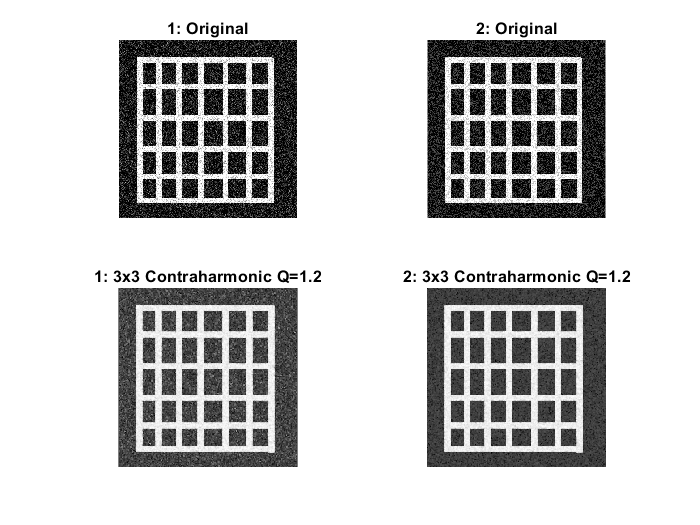


A_image = im2double(imread('Pattern1.jpg'));
B_image = im2double(imread('Pattern2.jpg'));
Q = 1.2;

A_image_mod_3x3 = zeros(size(A_image));
B_image_mod_3x3 = zeros(size(B_image));

mask_3x3 = [[1 1 1]
            [1 1 1]
            [1 1 1]];
mask_weight = sum(sum(mask_3x3));

for i = 1+1 : size(A_image,1)-1
    for j = 1+1 : size(A_image,2)-1
        
        frame_3x3 = [[A_image(i-1,j-1) A_image(i-1,j+0) A_image(i-1,j+1)]
                     [A_image(i+0,j-1) A_image(i+0,j+0) A_image(i+0,j+1)]
                     [A_image(i+1,j-1) A_image(i+1,j+0) A_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        A_image_mod_3x3(i,j) = sum(sum(masked.^(Q+1))) / sum(sum(masked.^(Q)));
    end
end
               
for i = 1+1 : size(B_image,1)-1
    for j = 1+1 : size(B_image,2)-1
        
        frame_3x3 = [[B_image(i-1,j-1) B_image(i-1,j+0) B_image(i-1,j+1)]
                     [B_image(i+0,j-1) B_image(i+0,j+0) B_image(i+0,j+1)]
                     [B_image(i+1,j-1) B_image(i+1,j+0) B_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        B_image_mod_3x3(i,j) = sum(sum(masked.^(Q+1))) / sum(sum(masked.^(Q)));
    end
end

figure();
subplot(2,2,1)
imshow(A_image);
title("1: Original");
subplot(2,2,2)
imshow(B_image);
title("2: Original");
subplot(2,2,3)
imshow(A_image_mod_3x3);
title("1: 3x3 Contraharmonic Q=1.2");
subplot(2,2,4)
imshow(B_image_mod_3x3);
title("2: 3x3 Contraharmonic Q=1.2");

Explanation: As seen in the image, and with the Q value of 1.2, the black areas are severely ruined by this filter with the white areas having a performance comparable to the white areas after any of the other previous filters.

## Contraharmonic Mean Filter (Q = -1.2)

clear

fprintf("Question 1, Contraharmonic Mean Filter (Q=-1.2):")

Question 1, Contraharmonic Mean Filter (Q=-1.2):

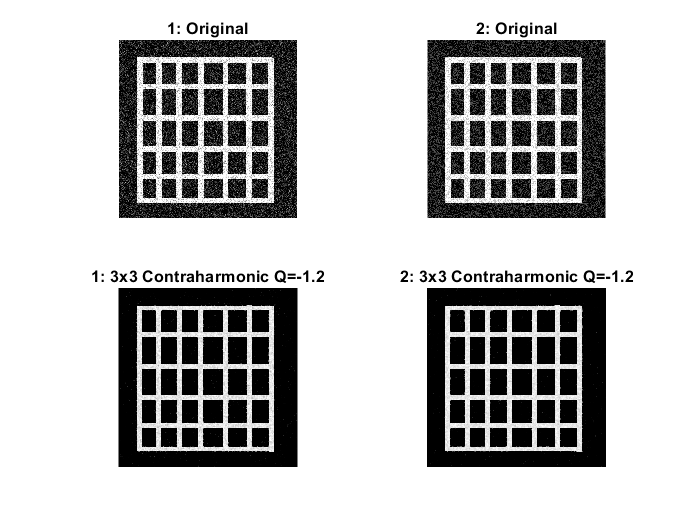


A_image = im2double(imread('Pattern1.jpg'));
B_image = im2double(imread('Pattern2.jpg'));
Q = -1.2;

A_image_mod_3x3 = zeros(size(A_image));
B_image_mod_3x3 = zeros(size(B_image));

mask_3x3 = [[1 1 1]
            [1 1 1]
            [1 1 1]];
mask_weight = sum(sum(mask_3x3));

for i = 1+1 : size(A_image,1)-1
    for j = 1+1 : size(A_image,2)-1
        
        frame_3x3 = [[A_image(i-1,j-1) A_image(i-1,j+0) A_image(i-1,j+1)]
                     [A_image(i+0,j-1) A_image(i+0,j+0) A_image(i+0,j+1)]
                     [A_image(i+1,j-1) A_image(i+1,j+0) A_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        A_image_mod_3x3(i,j) = sum(sum(masked.^(Q+1))) / sum(sum(masked.^(Q)));
    end
end
               
for i = 1+1 : size(B_image,1)-1
    for j = 1+1 : size(B_image,2)-1
        
        frame_3x3 = [[B_image(i-1,j-1) B_image(i-1,j+0) B_image(i-1,j+1)]
                     [B_image(i+0,j-1) B_image(i+0,j+0) B_image(i+0,j+1)]
                     [B_image(i+1,j-1) B_image(i+1,j+0) B_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        B_image_mod_3x3(i,j) = sum(sum(masked.^(Q+1))) / sum(sum(masked.^(Q)));
    end
end

figure();
subplot(2,2,1)
imshow(A_image);
title("1: Original");
subplot(2,2,2)
imshow(B_image);
title("2: Original");
subplot(2,2,3)
imshow(A_image_mod_3x3);
title("1: 3x3 Contraharmonic Q=-1.2");
subplot(2,2,4)
imshow(B_image_mod_3x3);
title("2: 3x3 Contraharmonic Q=-1.2");

Explanation: As seen in the image, and with the Q value of -1.2, the black areas are severely improved by this filter with the white areas having a performance comparable to the white areas after any of the other previous filters.

## Median Filter

clear

fprintf("Question 1, Median Filter:")

Question 1, Median Filter:

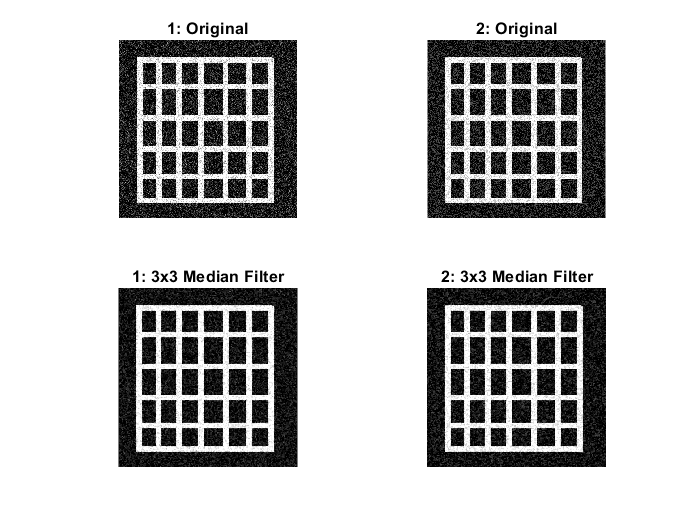


A_image = im2double(imread('Pattern1.jpg'));
B_image = im2double(imread('Pattern2.jpg'));

A_image_mod_3x3 = zeros(size(A_image));
B_image_mod_3x3 = zeros(size(B_image));

mask_3x3 = [[1 1 1]
            [1 1 1]
            [1 1 1]];
mask_weight = sum(sum(mask_3x3));

for i = 1+1 : size(A_image,1)-1
    for j = 1+1 : size(A_image,2)-1
        
        frame_3x3 = [[A_image(i-1,j-1) A_image(i-1,j+0) A_image(i-1,j+1)]
                     [A_image(i+0,j-1) A_image(i+0,j+0) A_image(i+0,j+1)]
                     [A_image(i+1,j-1) A_image(i+1,j+0) A_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        A_image_mod_3x3(i,j) = median(median(masked));
    end
end
               
for i = 1+1 : size(B_image,1)-1
    for j = 1+1 : size(B_image,2)-1
        
        frame_3x3 = [[B_image(i-1,j-1) B_image(i-1,j+0) B_image(i-1,j+1)]
                     [B_image(i+0,j-1) B_image(i+0,j+0) B_image(i+0,j+1)]
                     [B_image(i+1,j-1) B_image(i+1,j+0) B_image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        B_image_mod_3x3(i,j) = median(median(masked));
    end
end

figure();
subplot(2,2,1)
imshow(A_image);
title("1: Original");
subplot(2,2,2)
imshow(B_image);
title("2: Original");
subplot(2,2,3)
imshow(A_image_mod_3x3);
title("1: 3x3 Median Filter");
subplot(2,2,4)
imshow(B_image_mod_3x3);
title("2: 3x3 Median Filter");

Explanation: As you can see in the images, this median filter maintains the details of the patterns, while taking about half of the noise out. If this image was filtered multiple times using a median filter, it would likely be the best filter of the group.

2. Compare Spatial and Statistical Filters on Fig2.jpg

## Best Spatial Filter

clear

fprintf("Question 2, Best Spatial Filter:")

Question 2, Best Spatial Filter:

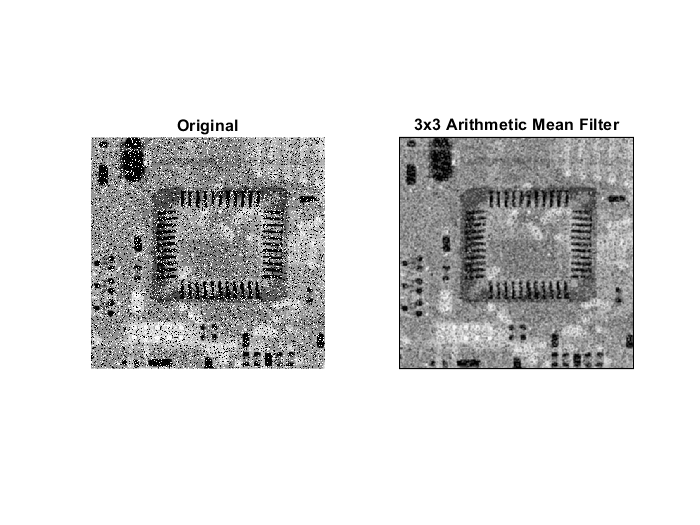


image = im2double(imread('Fig2.jpg'));
image_mod_3x3 = zeros(size(image));

mask_3x3 = [[1 1 1]
            [1 1 1]
            [1 1 1]];
mask_weight = sum(sum(mask_3x3));
Q = 0.1;

for i = 1+1 : size(image,1)-1
    for j = 1+1 : size(image,2)-1
        
        frame_3x3 = [[image(i-1,j-1) image(i-1,j+0) image(i-1,j+1)]
                     [image(i+0,j-1) image(i+0,j+0) image(i+0,j+1)]
                     [image(i+1,j-1) image(i+1,j+0) image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        image_mod_3x3(i,j) = sum(sum(masked)) / mask_weight;
    end
end

figure();
subplot(1,2,1)
imshow(image);
title("Original");
subplot(1,2,2)
imshow(image_mod_3x3);
title("3x3 Arithmetic Mean Filter");

Explanation: The 3x3 arithmetic mean filter does a decent job of clearing up the noise, but by far the best of the spatial filters, with both contraharmonics suffering from the other type of noise, and the geometric and harmonic filters favoring the dark areas too much. The issue with this filter is that it also blurred the fine details in the image.

## Best Statistical Filter Filter

clear

fprintf("Question 2, Best Statistical Filter:")

Question 2, Best Statistical Filter:

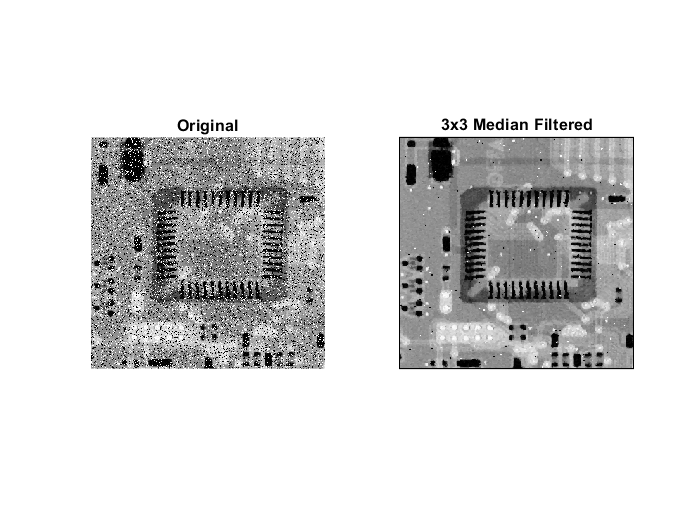


image = im2double(imread('Fig2.jpg'));

image_mod_3x3 = zeros(size(image));

mask_3x3 = [[1 1 1]
            [1 1 1]
            [1 1 1]];
mask_weight = sum(sum(mask_3x3));

for i = 1+1 : size(image,1)-1
    for j = 1+1 : size(image,2)-1
        
        frame_3x3 = [[image(i-1,j-1) image(i-1,j+0) image(i-1,j+1)]
                     [image(i+0,j-1) image(i+0,j+0) image(i+0,j+1)]
                     [image(i+1,j-1) image(i+1,j+0) image(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3;
        image_mod_3x3(i,j) = median(median(masked));
        
    end
end

figure();
subplot(1,2,1)
imshow(image);
title("Original");
subplot(1,2,2)
imshow(image_mod_3x3);
title("3x3 Median Filtered");

Explanation: As you can see in the image, this is clearly the best filter and achieves great results, especially when compared to the spatial filter. Results could be improved with multiple passes of the filter as well.

3.  Band Reject Filter out the sinusoidal noise in Fig3.jpg

clear

fprintf("Question 3:")

Question 3:

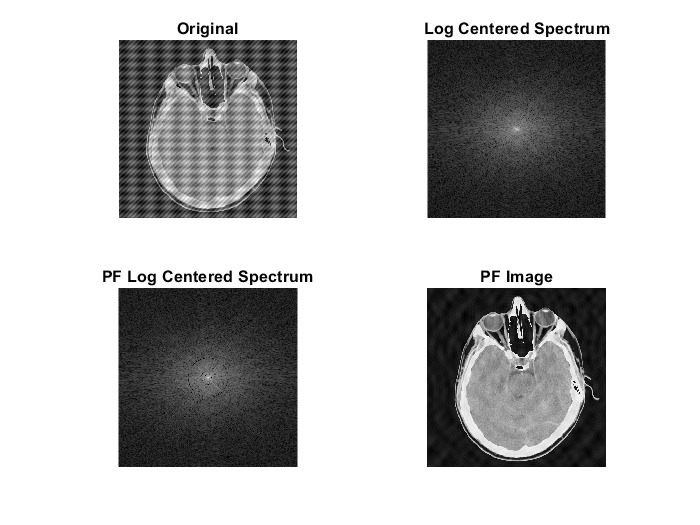


image = imread('Fig3.jpg');

[S, cS, eS] = cceFourierSpec(image);

C0_1 = 20;
W_1 = 0.1;
GBRF_1 = gbrf(image, C0_1, W_1);

C0_2 = 10;
W_2 = 0.1;
GBRF_2 = gbrf(GBRF_1, C0_2, W_2);

C0_3 = 56.5685425;
W_3 = 0.1;
GBRF_3 = gbrf(GBRF_2, C0_3, W_3);

[fS, fcS, feS] = cceFourierSpec(GBRF_3);

figure();
% Original Images
subplot(2,2,1)
imshow(image);
title("Original");

% Enhanced Centered Spectrums
subplot(2,2,2)
imshow(eS, []);
title("Log Centered Spectrum");

% Post Filter Centered Spectrums
subplot(2,2,3)
imshow(feS, []);
title("PF Log Centered Spectrum");

% Post Filter Images
subplot(2,2,4)
imshow(GBRF_3, []);
title("PF Image")

Explanation: As you can see from the images, there were three loci of noise in the spectrum, the vertical lines were 10 pixels from the center, the horizontal lines were 20 pixels from the center, and the sinusoidal diagonal lines were 40x40 pixels away resulting in being 56.56 pixels away from the center. Due to be able to exactly locate these loci allows the widths of each of the band reject filters to be very small resulting in minimal visual degradation from the image, such as blurring, while still removing all of the noise.

4. Add a Gaussian Blur to Fig4.jpg

clear

fprintf("Question 4:")

Question 4:

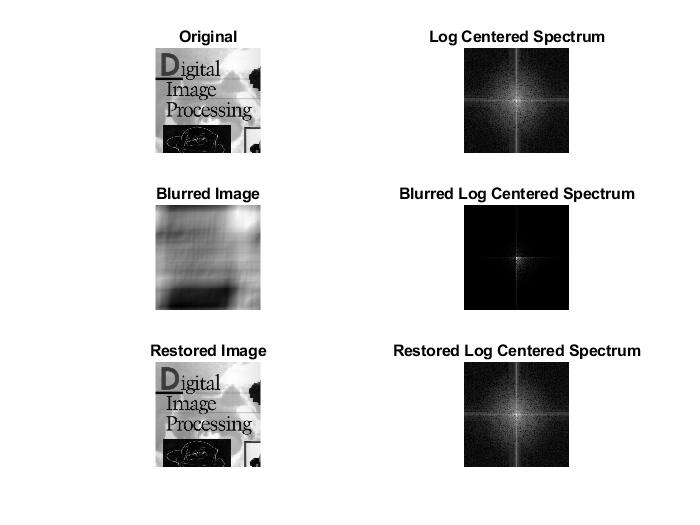


image = im2double(imread('Fig4.jpg'));

[S, cS, eS] = cceFourierSpec(image);
F = fft2(im2double(image));

uShift = 0.0981747704;
vShift = 0.0981747704;

H = zeros(size(image));
for u = 1 : size(image,1)
    for v = 1 : size(image,2)
        H(u,v) = (1/(pi*(uShift*u + vShift*v))) * (sin(pi*(uShift*u + vShift*v))) * (exp(-1*1j*(uShift*u + vShift*v)));
    end
end
H_inv = 1 ./ H;

G = H .* F;

F_rest = H_inv .* G;

figure();
% Original Image
subplot(3,2,1)
imshow(image);
title("Original");
subplot(3,2,2)
imshow(eS, []);
title("Log Centered Spectrum");

% Blurred Image
subplot(3,2,3)
imshow(real(ifft2(G)), []);
title("Blurred Image")
subplot(3,2,4)
imshow(log(1+abs(fftshift(G))), []);
title("Blurred Log Centered Spectrum");

% Restored Image
subplot(3,2,5)
imshow(real(ifft2(F_rest)), []);
title("Restored Image")
subplot(3,2,6)
imshow(log(1+abs(fftshift(F_rest))), []);
title("Restored Log Centered Spectrum");

Explanation: As you can see in the images, the blur filter was successfully applied and the new spectrum shown with an effective shift of all of the frequencies to the bottom right. The inverse of this filter was then calculated and applied to the blurry image to restore it perfectly, as seen in the spectrum.

## Appendix (Functions Used)

function [S,cS,eS] = cceFourierSpec(imag)
% Description: Compute, Center, and Enhance a Fourier Spectrum of an Image

% Base FFT
F = fft2(im2double(imag));

% Spectrum
S = abs(F);

% Centered Spectrum
cF = fftshift(F);
cS = abs(cF);

% Enhanced Spectrum
eS = log(1+abs(cF));
end

%%%%%%%%% Band Reject Filters %%%%%%%%%
function filtered = gbrf(imag, C0, W)
% Description: Perform an Gaussian Band Reject Filter to an image with the given
% Center and Width of the band

% Initial variables
[M,N] = size(imag);
F = fft2(im2double(imag));

% Mesh grid generation
u = 0:(M-1);
v = 0:(N-1);
idx = find(u>M/2);
u(idx)= u(idx)-M;
idy = find(v>N/2);
v(idy)= v(idy)-N;
[U,V] = meshgrid(v,u);
D = sqrt(U.^2+V.^2);

% Gaussian Filter
H = 1-exp(-(((D-C0).^2)./(D.*W^2)));

% Apply Filter
G = F.*H;
filtered = real(ifft2(G));
end